# Cell type identification

Unit classficiation were done as described below.

Units were first classified based on trough-to-peak latency quantified on unfiltered spike waveforms. (Senzai et al., 2019). This step resulted in two population of units: narrower-waveform spike units (putative interneurons) and wider-waveform spike units (putative principal neurons).

## Load data

## Load data

clear all
% Load the table of rec info
ParDir = 'Z:\users\Tatsumi\data\MultiReward'; % parent directory
recListPath = 'H:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Multireward_exp_list_2024.xlsx'; % table of rec info
allRecs = GetRecList(recListPath); % load the rec info list

% Specify the index of session to be loaded
%% 240207
recID = 3;
% recID = 4;
% recID = 5;
%% 240208
% recID = 6;
% recID = 7;
% recID = 8;
%% 240209_1
% recID = 9;
% recID = 10;
%% 240209_2
% recID = 11;
%% 240210_1
% recID = 12;
% recID = 13;
%% 240210_2
% recID = 14;
%% 240211_1
% recID = 15;
% recID = 16;
% recID = 17;
%% 240211_2
% recID = 18;
%% 240212
% recID = 19;
% recID = 20;
% recID = 21;


% general information
expType = allRecs.expType{recID}; % experiment type: social/solo/tethered
rewardType = allRecs.rewardType{recID}; % reward type: multi/single flavor
rootdir = fullfile(ParDir,allRecs.rootdir{recID}); % root directory of the recording
ephysDir = fullfile(rootdir,'ephys',allRecs.ephysDir{recID}); % ephys directory
recDate = char(allRecs.date(recID),'MM/dd/yy'); % date of recording
recName = allRecs.recName{recID};
bname_ephys = allRecs.ephysBat{recID}; % name of ephys bat
probeNum = allRecs.probeNum(recID); % probe number
trjName = allRecs.trjName{recID}; % trajectory

cd(rootdir)

% Create output directories
outDir = fullfile(rootdir,'analysis'); % output
figDir = fullfile(rootdir,'analysis','figure'); % figure
if isempty(dir(outDir)); mkdir(outDir); end
if isempty(dir(figDir)); mkdir(figDir); end

% load data
dataTypes = 'barsm'; % data types to be loaded
[BhvData,AnalogData,RewardData,spikeData,mtData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data

Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240207 ...
Loading analog signals ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading behavioral data ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading reward data ...
Final MinPeakDistance was 0.5 
322 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.
Loading spike data ...
Kilosort outputs found
Manual curation found
Loading meta data ...


% Landings = extractLandings(BhvData,RewardData,mtData,'include','all');
[Flights, TrjCluster] = extractFlights(BhvData,RewardData,mtData,'include','all');

% Global Figure directory
GbFigDir = 'F:\Data\GroupForaging\Analysis\figure';

### Layer information

Layers = struct([]);

%%% 14633, MEC_2
Layers(1).batid = '14633';
Layers(1).trjName = 'MEC_2'; % name of trajectory

Layers(1).layer(1).name = 'MEC';
Layers(1).layer(1).depth = [0,2800];
Layers(1).layer(1).color = [127,201,127]/255;

Layers(1).layer(2).name = 'VC';
Layers(1).layer(2).depth =[5500,8000];
Layers(1).layer(2).color = [190,174,212]/255;

Layers(1).layer(3).name = 'unknown';
Layers(1).layer(3).depth = [0,0];
Layers(1).layer(3).color = [0,0,0];

%%% 14662, dCA1_MEC_3
Layers(2).batid = '14662'; % id of bat
Layers(2).trjName = 'dCA1_MEC_3'; % name of trajectory
Layers(2).layer(1).name = 'MEC';
Layers(2).layer(1).depth = [0,500];
Layers(2).layer(1).color = [127,201,127]/255;

Layers(2).layer(2).name = 'Subiculum';
Layers(2).layer(2).depth =[500,1600];
Layers(2).layer(2).color = [190,174,212]/255;

Layers(2).layer(3).name = 'DG';
Layers(2).layer(3).depth =[1600,4100];
Layers(2).layer(3).color = [253,192,134]/255;

Layers(2).layer(4).name = 'Subiculum';
Layers(2).layer(4).depth =[4100,5200];
Layers(2).layer(4).color = [190,174,212]/255;

Layers(2).layer(5).name = 'VC';
Layers(2).layer(5).depth =[4100,5200];
Layers(2).layer(5).color = [150,150,150]/255;

Layers(2).layer(6).name = 'unknown';
Layers(2).layer(6).depth = [0,0];
Layers(2).layer(6).color = [0,0,0];


%%% 14662, dCA1_vCA1_3
Layers(3).batid = '14662'; % id of bat
Layers(3).trjName = 'dCA1_vCA1_3'; % name of trajectory

Layers(3).layer(1).name = 'CA1';
Layers(3).layer(1).depth =[0,1700];
Layers(3).layer(1).color = [190,174,212]/255;

Layers(3).layer(2).name = 'CA3';
Layers(3).layer(2).depth = [1700, 3300];
Layers(3).layer(2).color = [253,192,134]/255;

Layers(3).layer(3).name = 'CA1';
Layers(3).layer(3).depth =[3300,4100];
Layers(3).layer(3).color = [190,174,212]/255;

Layers(3).layer(4).name = 'unknown';
Layers(3).layer(4).depth = [0,0];
Layers(3).layer(4).color = [0,0,0];


% Assign region to the spike data structure
unit_ids = spikeData.good_units.cluster_id;
regions = cell(length(unit_ids),1);
for unit = 1:length(unit_ids)
    unit_id = unit_ids(unit);
    depth = spikeData.good_units.depth(unit); % depth of unit
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = get_probe_region(layers,depth);
    regions{unit} = region;
end
spikeData.good_units.region = regions;


## Extract waveforms

path_recdir = fullfile(ephysDir,bname_ephys,'Processed');
waveData = getSpikeWaveforms(path_recdir,probeNum);

Kilosort outputs found.
Manual curation found



% % Save directory
% FigDir = fullfile(GbFigDir,'SpikeWaveforms',sprintf('Ephys%s_%s',bname_ephys,trjName),recName);
% if isempty(dir(FigDir));  mkdir(FigDir); end
% for i = 1:length(waveData.waveforms)
% % for i = 1:1
%     unit = waveData.waveforms(i).unit; % unit id
%     wv_window = waveData.window; % time range
%     wv = waveData.waveforms(i).raw_mean; % waveform
%     % 
%     y_max = max(wv);
%     y_min = min(wv);
%     wv = (wv-y_min)/(y_max-y_min); % normalize to [0 1]
% 
%     t_wv = wv_window(1):1/30:wv_window(2);
% 
%     % fig = figure('Visible','off'); hold on
%     % plot(t_wv,wv,'Color',[150,150,150,10]/255)
%     % plot(t_wv,mean(wv,1),'k','LineWidth',1)
%     % hold off
%     fig = figure('Visible','off');
%     plot(t_wv,wv,'k','LineWidth',1)
%     title(sprintf('Unit %d',unit))
%     % xlabel('Time (ms)')
%     ylabel('Amplitude (uv)')
%     set(gca,'XColor','none','YColor','none','FontSize',14)
%     ylim([-0.1 1.2])
% 
%     patch([1 1.5 1.5 1], ...
%         [0.02 0.02 0.03 0.03],'k','clipping','off')
%     text(1.25,-0.05, '0.5ms', 'fontsize', 14, 'HorizontalAlignment','center')
% 
%     saveas(fig,fullfile(FigDir,sprintf("unit%d.png",unit)))
% end

% Add spike features
[waveData.waveforms.region] = spikeData.good_units.region{:};
n_unit = spikeData.numGoodUnits;
for unit = 1:n_unit
    spikeData.good_units.trough2peak(unit) = waveData.waveforms(unit).troughtoPeak;
end
spikeData.good_units.celltype = cell(n_unit,1);
spikeData.good_units.celltype(spikeData.good_units.trough2peak <= 0.3) = {'Interneuron'};
spikeData.good_units.celltype(spikeData.good_units.trough2peak > 0.3) = {'Excitatory'};

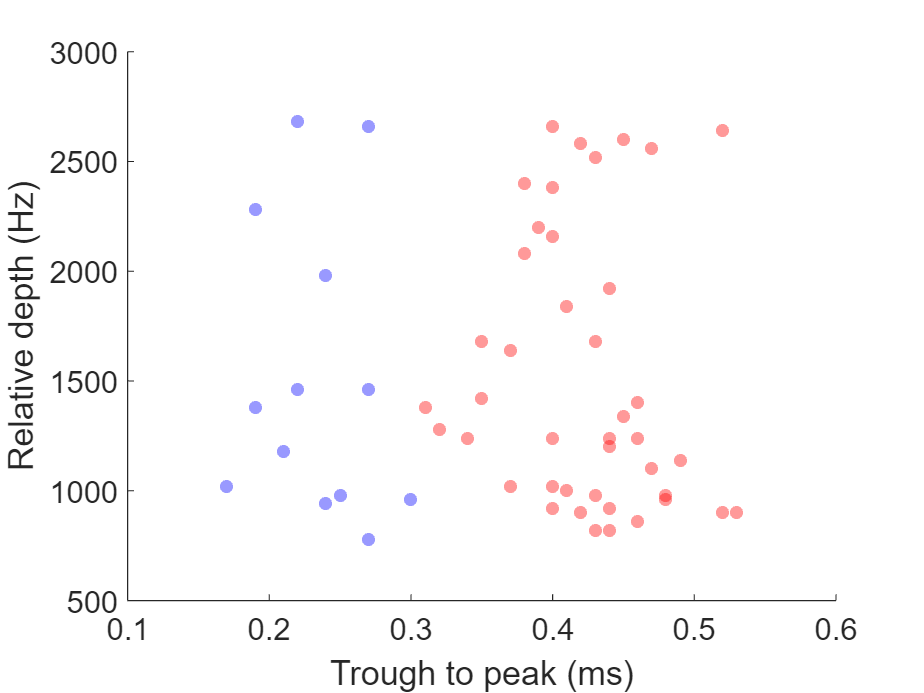


% Cell type classification based on physiological features
target_units = strcmp(spikeData.good_units.region,'MEC');
% target_units = 1:spikeData.numGoodUnits;
trough2peak = [spikeData.good_units.trough2peak]; trough2peak = trough2peak(target_units);
unit_depth = [spikeData.good_units.depth]; unit_depth = unit_depth(target_units);
unit_fr = [spikeData.good_units.fr]; unit_fr = unit_fr(target_units);
celltype = [spikeData.good_units.celltype]; celltype = celltype(target_units);

FigDir = fullfile(GbFigDir,'Cell_classification',sprintf('Ephys%s_%s',bname_ephys,trjName),recName);
if isempty(dir(FigDir));  mkdir(FigDir); end

fig = figure;
hold on
scatter(trough2peak(strcmp(celltype,'Interneuron')),unit_depth(strcmp(celltype,'Interneuron')),'b','filled','o','MarkerFaceAlpha',0.4)
scatter(trough2peak(strcmp(celltype,'Excitatory')),unit_depth(strcmp(celltype,'Excitatory')),'r','filled','o','MarkerFaceAlpha',0.4)
hold off

ylabel('Relative depth (Hz)')
xlabel('Trough to peak (ms)')
set(gca,'FontSize',14)

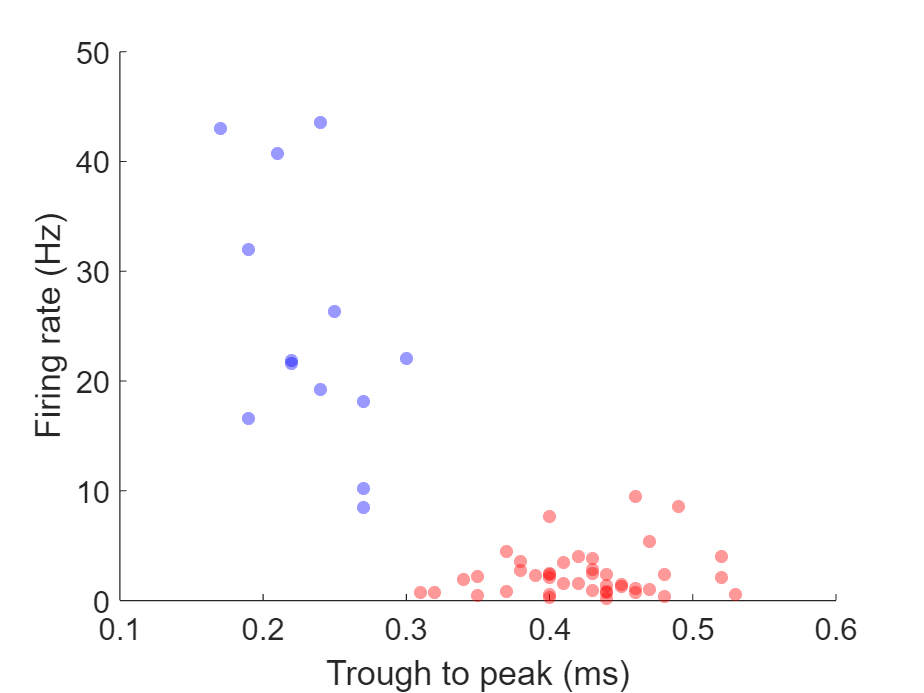

saveas(fig,fullfile(FigDir,'Trough2Peak_depth.png'))

fig = figure;
hold on
scatter(trough2peak(strcmp(celltype,'Interneuron')),unit_fr(strcmp(celltype,'Interneuron')),'b','filled','o','MarkerFaceAlpha',0.4)
scatter(trough2peak(strcmp(celltype,'Excitatory')),unit_fr(strcmp(celltype,'Excitatory')),'r','filled','o','MarkerFaceAlpha',0.4)
hold off

ylabel('Firing rate (Hz)')
xlabel('Trough to peak (ms)')
set(gca,'FontSize',14)


saveas(fig,fullfile(FigDir,'Trough2Peak_fr.png'))



### Save data

celltype = spikeData.good_units.celltype;
trough2peak = spikeData.good_units.trough2peak;
save(fullfile(FigDir,'celltype.m'),'celltype','trough2peak')